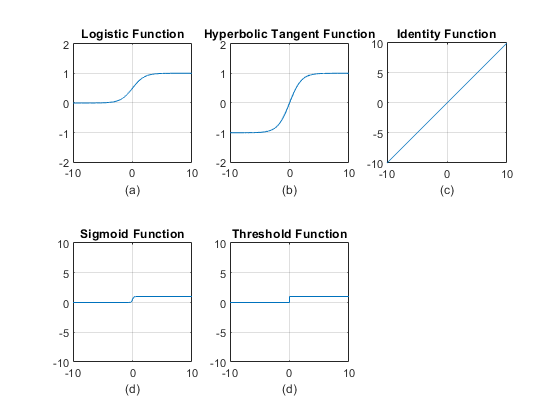

clc
clear all
x = -10:0.01:10;
tmp = exp(-x);
y1 = 1./(1+tmp);
y2 = (1-tmp)./(1+tmp);
y3 = x;
tm = exp(-10.*x);
y4=1./(1+tm);
[xx,xy]=find(x>=0);
x3=zeros(1,2000);
x3(xy)=1;

subplot(231); 
plot(x, y1); 
grid on;
axis([min(x) max(x) -2 2]);
title('Logistic Function');
xlabel('(a)');
axis('square');

subplot(232);
plot(x, y2);
grid on;
axis([min(x) max(x) -2 2]);
title('Hyperbolic Tangent Function');
xlabel('(b)');
axis('square');

subplot(233); 
plot(x, y3); 
grid on;
axis([min(x) max(x) min(x) max(x)]);
title('Identity Function');
xlabel('(c)');
axis('square');

subplot(234); 
plot(x, y4); 
grid on;
axis([min(x) max(x) min(x) max(x)]);
title('Sigmoid Function');
xlabel('(d)');
axis('square');

subplot(235); 
plot(x, x3); 
grid on;
axis([min(x) max(x) min(x) max(x)]);
title('Threshold Function');
xlabel('(d)');
axis('square');